Fall 2023 ModSim Project 2

Zara Coakley, Dongim Lee

**1. Question** 

**1-1. Modeling Question and Categorization**

Our modeling question is how does being in the Nord vs outside affect the maximum popularity of the most popular meme. It is a predictive question. 

**1-2. Importance / Interest**

This is an important question because it will help Zach make informed decisions about how to run the meme game in the future. If he wants to make changes to the meme game that affect the popularity that memes reach, he will better understand how the physical mobility of the people playing will affect that.

**1-3. Background Information and References**

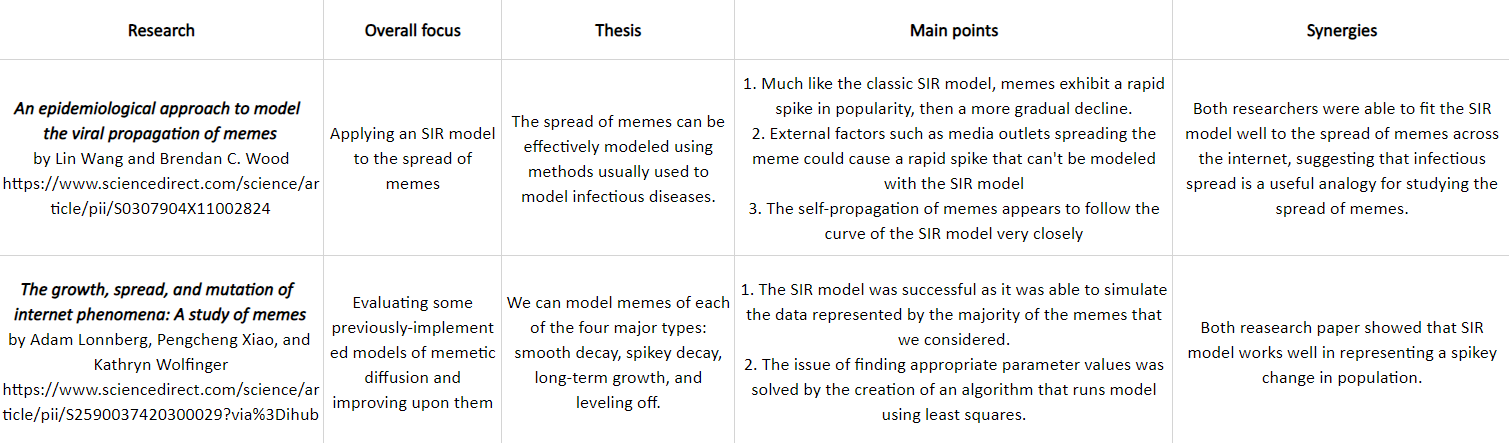

Table 1. A research synthesis matrix for background information

**2. Methodology/Model**

**2-1. Description**

We created an agent-based model that tracks which three memes each person in the meme game has over the course of the game. It returns a state matrix S, which is a 90x90x25 matrix, with each row representing a person, each column representing a meme, and each “sheet” representing a timestep. Each entry in the matrix is a zero, one, two, or three, representing how many of that particular meme a particular person has on a particular timestep.

Our action function simulates 25 rounds, and in each round it pairs everyone up. Each person’s partner is determined semi-randomly, weighted by an adjacency matrix, M. 

Person i's partner = max(1 x 90 matrix of random numbers * M(i)) 

The adjacency matrix is dependent on the space (Nord vs. outside). Within each pair, each person gives one of their memes (determined randomly) to their partner, then randomly discards one of their previous memes. The function tries to partner together people who haven’t been partners in previous rounds, but doesn’t strictly prohibit repeat partners in order to ensure that everyone ends up with a partner (it can end up where the only two people left without partners have already been partnered in a previous round. In that case they will still partner up). 

Assumptions relating to our function: 

- We assume that all memes are identical and equally likely to spread 

- Our modeling question is about how being in the Nord changes the spread of memes in general, not how any specific memes spread, so it is reasonable to treat all memes as the same. 

- We assume that everyone follows the rules, only spreading memes they already own and not creating new memes in the middle of the game 

- Although this did happen in the real meme game, most memes passed on were legitimate, so it probably had a minimal effect on the final popularity of the rest of the memes 

Assumptions relating to our graphs: 

- Our model simplifies the process of picking partners in the Nord by deciding at the beginning of the game on a set of people that each person is likely to interact with. In reality, people may move around the room, and the people they are likely to interact with at the beginning of the game may not be the same as toward the end. 

- We think this is a reasonable choice because given the limited space in the Nord, people are going to be crowded in the aisles and not able to move huge distances in the time they are given to find a partner. Because of this the set of people near them should stay relatively similar. If the meme game lasted for more rounds, say 100, this assumption might be less useful

We ran our action function on two different graphs: one to represent the Nord and one to represent outside. Our graph of the Nord looks like this:

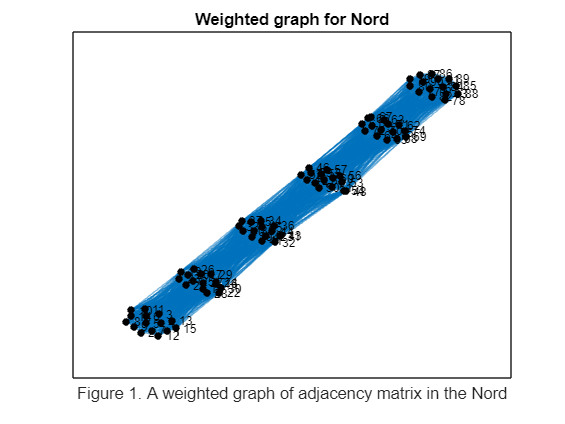

% graph for adjacency matrix in the nord
M_res = make_adj_pods(15, 1, 2);
M_zeros = zeros(15);
M_ones = ones(15);

M = [M_res M_ones M_zeros M_zeros M_zeros M_zeros;
    M_ones M_res M_ones M_zeros M_zeros M_zeros;
    M_zeros M_ones M_res M_ones M_zeros M_zeros;
    M_zeros M_zeros M_ones M_res M_ones M_zeros;
    M_zeros M_zeros M_zeros M_ones M_res M_ones;
    M_zeros M_zeros M_zeros M_zeros M_ones M_res;
    ];

GraphM = graph(M);
figure()
h = plot(GraphM, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title("Weighted graph for Nord");
xlabel("Figure 1. A weighted graph of adjacency matrix in the Nord");

We assume a group of 90 students, organized into six rows of 15 people. The people in each row are strongly connected to each other (weight 2), weakly connected to the people in the rows directly above and below them (weight 1), and extremely weakly connected to everyone else (weight 0.001).

We chose to represent it this way by looking at the routes of movement people had access to. People will move across the row, but they will most likely not climb over seats to change rows. Because of this, we assumed that there will be enough mixing within the row that a given person has a similar chance of partnering with any person in their row. We also assumed that people will be less likely but still likely to partner with someone in the row directly above or below because people in that row are physically further away that someone in the same row, but still within easy talking distance. Anyone in rows beyond directly above and below would be very difficult to talk to, so we made the chance of them partnering up very unlikely. 

Our graph of outside is a complete graph. Everyone is connected equally to everyone else.

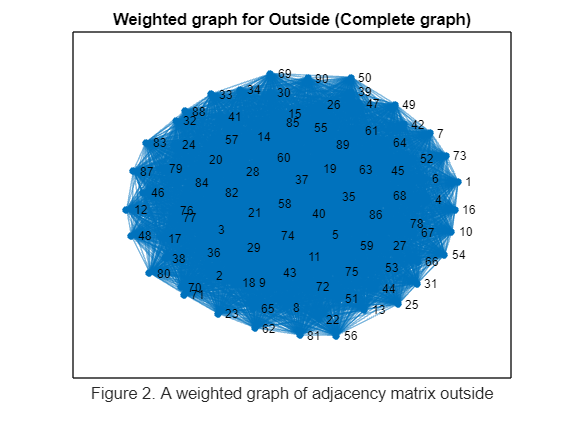

% graph for adjacency matrix outside
Graph_complete = graph(~eye(90)); 
figure()
plot(Graph_complete)
title("Weighted graph for Outside (Complete graph)");
xlabel("Figure 2. A weighted graph of adjacency matrix outside");

We represented outside as a complete graph because people are free to move around anywhere in the space without obstacles, and during the game players were specifically given instructions to mix as much as possible. Because of this, players should have an equal chance of talking to any other player in the game.

**2-2. Development**

% simulation for Nord
M_res = make_adj_pods(15, 1, 2);
M_zeros = ones(15)*.0001;
M_ones = ones(15);

M_nord = [M_res M_ones M_zeros M_zeros M_zeros M_zeros;
    M_ones M_res M_ones M_zeros M_zeros M_zeros;
    M_zeros M_ones M_res M_ones M_zeros M_zeros;
    M_zeros M_zeros M_ones M_res M_ones M_zeros;
    M_zeros M_zeros M_zeros M_ones M_res M_ones;
    M_zeros M_zeros M_zeros M_zeros M_ones M_res;
    ]; % 90*90 edge matrix (adjacency matrix)

sim_time = 1000;
Result_nord = zeros(sim_time, 2);

for c=1:sim_time
    S_nord = simulate_abmeme(M_nord, 25);
    Sum_nord = sum(S_nord, 1);
    Sum_reshape_nord = reshape(Sum_nord, [], 2250);
    [Max_nord, idx_nord] = max(Sum_reshape_nord);
    max_meme_number_nord = rem(idx_nord, 90);
    Result_nord(c, 1) = Max_nord;
    Result_nord(c, 2) = max_meme_number_nord;
end

Nord = mean(Result_nord(:, 1))

Nord = 28.4220


% simulation for outside
M_outside=~eye(90);

Result_outside = zeros(sim_time, 2);

for c=1:sim_time
    S_outside = simulate_abmeme(M_outside, 25);
    Sum_outside = sum(S_outside, 1);
    Sum_reshape_outside = reshape(Sum_outside, [], 2250);
    [Max_outside, idx_outside] = max(Sum_reshape_outside);
    max_meme_number_outside = rem(idx_outside, 90);
    Result_outside(c, 1) = Max_outside;
    Result_outside(c, 2) = max_meme_number_outside;
end

Outside = mean(Result_outside(:, 1))

Outside = 29.2370

*Verification*

To verify our model, we came up with multiple verification facts: 

- Everyone should have three memes at all times, except for the first and second round, when they should have one and two memes, respectively .

- A meme’s popularity can only increase by an amount less than or equal to its current popularity.

% verification
for i = 1:90
    assert(sum(S_nord(i, :, 1))==1, "everyone should have one meme in the first round")
    assert(sum(S_nord(i, :, 2))==2, "everyone should have two memes in the second round")
    for j = 3:25
        assert(sum(S_nord(i, :, j))==3, "everyone should have three memes after third round")
    end
end



for t=2:25
    for i=1:90
        diff = sum(S_nord(:, i, t))-sum(S_nord(:, i, t-1));
        if diff>0
            assert(diff<=sum(S_nord(:, i, t-1)), "for every next timestep, the number of memes increased cannot exceed the previous number of memes")
        end
    end
end

**2-3. Validation**

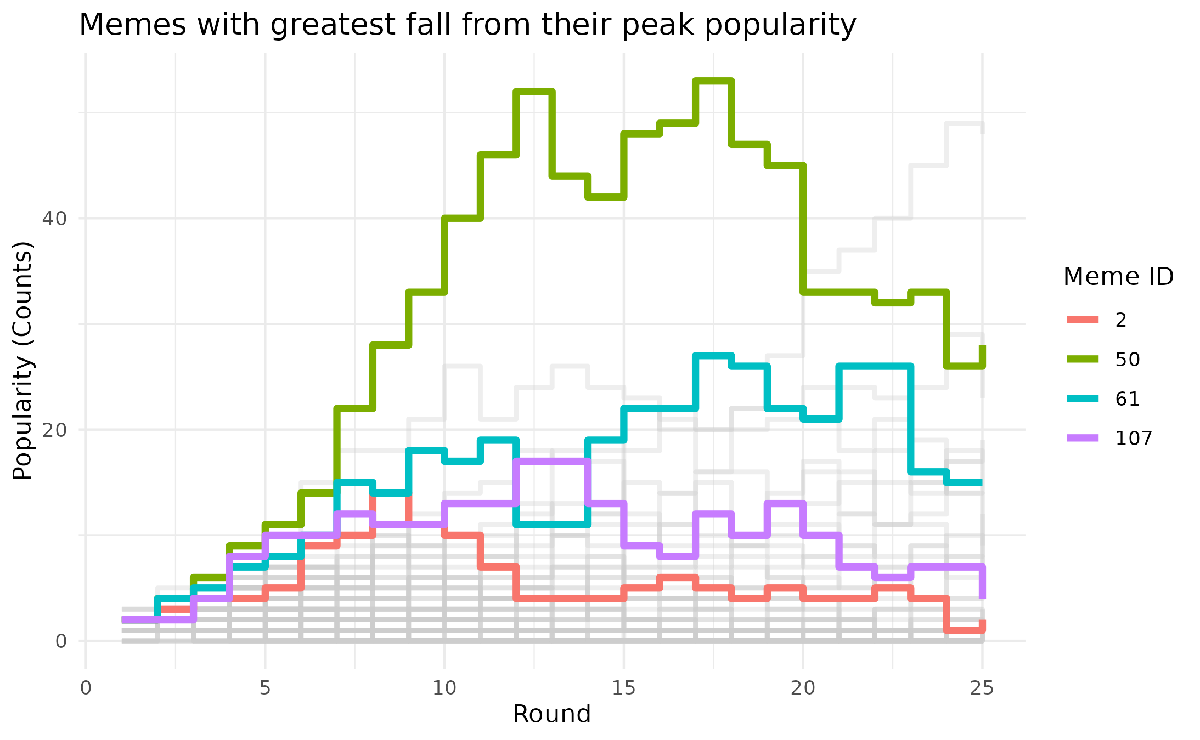

Figure 3. A graph of memes' popularity by round for the meme game on the first day of ModSim

We used the meme game data on the first day of ModSim to validate our model. The graph derived from the meme game data on the first day of ModSim indicated a peak number of 53, while our model, after 1000 simulations, provided an average peak number of 30. However, during each simulation, the majority of peak numbers ranged from approximately 18 to 61, effectively encompassing the peak number from the actual meme game data. This reinforces the validation of our model. 

min_peak = min(Result_outside(:, 1))

min_peak = 16

max_peak = max(Result_outside(:, 1))

max_peak = 59

Furthermore, the trend exhibited by each meme within our model, depicting their respective fluctuations and trends in growth and decline, closely mirrors the patterns observed in real-world data. This consistency between the behavior of memes in our model and their real-world counterparts serves to further validate the accuracy of our model.

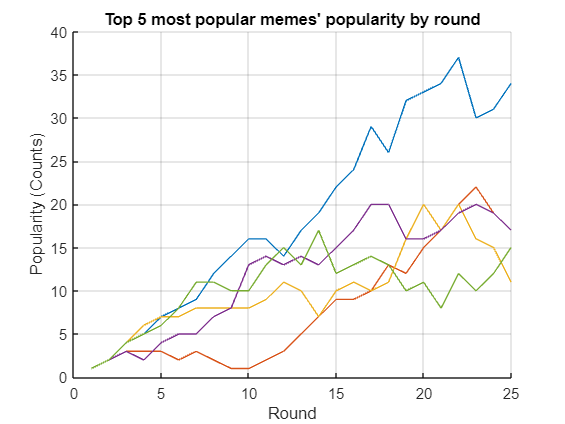

% validation
S_outside = simulate_abmeme(M_outside, 25);
meme_popularities_3D = sum(S_outside, 1);
meme_popularities = reshape(meme_popularities_3D, 90, 25); %each column is a timestep
max_each_meme = max(meme_popularities, [], 2);
[sorted, sorted_idx] = sort(max_each_meme, 'descend');

figure()
hold on
for i = sorted_idx(1:5) %iterating through each meme
    plot(1:25, meme_popularities(i,:))
end
xlabel("Round");
ylabel("Popularity (Counts)");
title("Top 5 most popular memes' popularity by round");
grid on;

disp("Figure 4. A graph of top 5 most popular memes' popularity (outside)");

Figure 4. A graph of top 5 most popular memes' popularity (outside)


**3. Result**

**3-1. Metrics and Sweeps**

We used the peak popularity of the most popular meme as our metric. To account for randomness, we conducted 1000 simulations and then derived the average peak popularity from these simulations. 

Since our modeling question is about comparing the peak popularity of the most popular meme for the Nord vs outside scenarios, our metric is directly related to our modeling question. 

We conducted a discrete parameter sweep over the adjacency matrix, using two distinct matrices: M_nord (adjacency matrix for in-Nord scenarios) and M_outside (adjacency matrix for outside scenarios). 

Our analysis revealed that the peak popularity of the most popular meme in the Nord was 28.5, while outside scenarios yielded a peak popularity of 29.5. There exists a difference in the metrics between playing in the Nord and playing outside, that the peak popularity is slightly lower in the Nord. This difference can be attributed to the higher likelihood of players in the Nord partnering with those in the same row or closer rows, resulting in some kind of “podding” situation, limiting memes to spread more.

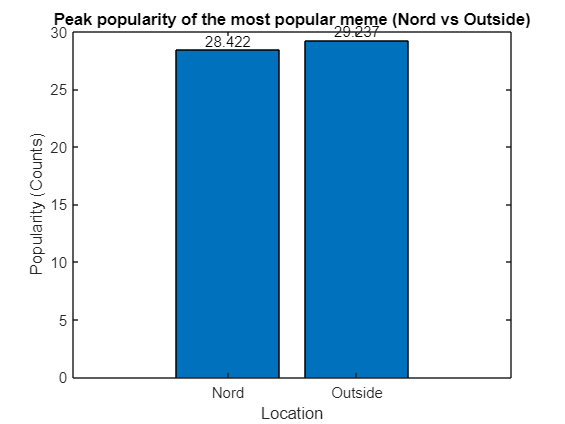

% parameter sweep result
figure()
x=["Nord"; "Outside"];
w=[Nord; Outside];
bar(w)
xticklabels(x);
xlabel("Location");
ylabel("Popularity (Counts)");
title("Peak popularity of the most popular meme (Nord vs Outside)");
text(1,w(1),num2str(w(1)'),'vert','bottom','horiz','center'); 
text(2,w(2),num2str(w(2)'),'vert','bottom','horiz','center'); 

disp("Figure 5. A bar graph comparing the peak popularities of the most popular meme between Nord and outside scenarios");

Figure 5. A bar graph comparing the peak popularities of the most popular meme between Nord and outside scenarios


**3-2. Analysis**

Playing in the Nord lowers the peak popularity of the most popular meme, primarily due to constraints on player movement and a higher likelihood of players forming partnerships with those in close proximity. On the other hand, the outside scenario presents a relatively higher peak popularity, largely attributable to the freedom of player movement and the equal opportunity for players to partner with anyone.

**4. Interpretation**

**4-1. Therefore**

Our modeling question is how does playing the meme game in the Nord vs outside affect the maximum popularity of the most popular meme?

Based on our model, playing in the Nord appears to decrease the maximum popularity of the most popular meme by about one meme on average. However, this is averaged over 1000 trials, and from one game to the next the popularity varies by much more than one meme just due to chance, so in practice there will not be a noticeable difference in how popular the most popular meme becomes when you play in either space.

**4-2. Limitations and Further Work**

*Limitations* 

Our model doesn’t account for the fact that people on the edges of rows can easily move along the aisles to interact with people on the edges of other rows. We figured that people along the edges of rows were a small enough subset of people playing the game that they could be ignored. If the rows had fewer people in them, say five instead of fifteen, this assumption would not hold. 

Additionally, within rows people are probably not equally as likely to interact with a person ten seats down from them as they are to interact with the person next to them, as they are in our model. This and the above point mean that the podding structure we defined in our model for the Nord isn’t accurate to the real pattern of interactions in the Nord. However, the main feature of the Nord that we are interested in is that people have limited mobility and can only talk to people near them, and our model as it is does have that feature. 

Our model also assumes that all memes are equally likely to be passed forward/covered up. We decided this was okay for doing a qualitative comparison between outside and the Nord (memes tend to get a bit less popular in the Nord), but if we wanted to actually predict how popular the most popular meme will get, we would need to consider that some memes are going to be more likely to be passed on than others because if people like a specific meme and pass it on a lot it will be more likely to reach a higher total than if they were just passing along memes randomly. 

This may be why the fish meme’s popularity, at 53, was so much higher than the average popularity of the most popular meme from our outside model, 29.5. People specifically tried to pass on the fish meme, whereas in our model everyone chose randomly which meme to pass on. 

*Further Work*

Some improvements we could make to improve confidence in our model: 

- Do actual research on how people move in the Nord to better inform our decisions of how to structure the graph. This might involve playing a game in the Nord and analyzing who partnered with who. 

- Look at other metrics beyond just the popularity of the most popular meme. For example, we could look at how the mean curve changes (ex. its peak, timing, or width) 

- Instead of just looking at the Nord and outside, we could do a continuous parameter sweep over a variable representing how quickly a person’s connection to other people decays with distance. The outside scenario would be a one extreme, with no decay, and we could see how much different levels of immobility in a space affect the popularity of memes in the meme game.

% additional work
% what happens when we allow players to partner with the same partner

Result_nord_allow = zeros(sim_time, 2);

for c=1:sim_time
    S_nord_allow = simulate_abmeme_allow(M_nord, 25);
    Sum_nord_allow = sum(S_nord_allow, 1);
    Sum_reshape_nord_allow = reshape(Sum_nord_allow, [], 2250);
    [Max_nord_allow, idx_nord_allow] = max(Sum_reshape_nord_allow);
    max_meme_number_nord_allow = rem(idx_nord_allow, 90);
    Result_nord_allow(c, 1) = Max_nord_allow;
    Result_nord_allow(c, 2) = max_meme_number_nord_allow;
end

Nord_allow = mean(Result_nord_allow(:, 1))

Nord_allow = 27.5450


Result_outside_allow = zeros(sim_time, 2);

for c=1:sim_time
    S_outside_allow = simulate_abmeme_allow(M_outside, 25);
    Sum_outside_allow = sum(S_outside_allow, 1);
    Sum_reshape_outside_allow = reshape(Sum_outside_allow, [], 2250);
    [Max_outside_allow, idx_outside_allow] = max(Sum_reshape_outside_allow);
    max_meme_number_outside_allow = rem(idx_outside_allow, 90);
    Result_outside_allow(c, 1) = Max_outside_allow;
    Result_outside_allow(c, 2) = max_meme_number_outside_allow;
end

Outside_allow = mean(Result_outside_allow(:, 1))

Outside_allow = 29.3560

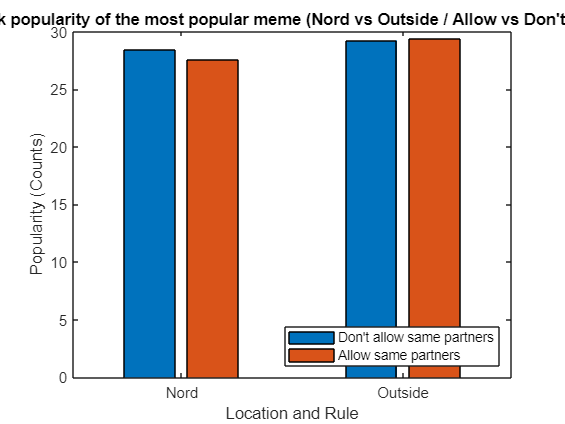


figure()
x=["Nord", "Nord allow"; "Outside", "Outside allow"];
y=[Nord, Nord_allow; Outside, Outside_allow];
bar(y)
xticklabels(x);
xlabel("Location and Rule");
ylabel("Popularity (Counts)");
legend({"Don't allow same partners", "Allow same partners"}, 'Location', 'southeast');
title("Peak popularity of the most popular meme (Nord vs Outside / Allow vs Don't allow)");

disp("Figure 6. A bar graph comparing the peak popularities of the most popular meme for different location(Nord or outside) and rule(allow the same partner or not)");

Figure 6. A bar graph comparing the peak popularities of the most popular meme for different location(Nord or outside) and rule(allow the same partner or not)


function M_res = make_adj_pods(n_per_pod, n_pods, pod_effect)
% Construct an adjacency matrix for a "podding" scenario
%
% Usage
%   M_res = make_adj_pods(n_per_pod, n_pods, infectivity)
%
% Arguments
%   n_per_pod  = number of persons per "pod"
%   n_pods     = total number of pods; total population = n_per_pod * n_pods
%   pod_effect = relative infectivity within pods; should be infectivity > 1
%
% Returns
%   M_res = adjacency matrix for desired graph
n_total = n_per_pod * n_pods;

% Create the "base matrix" with weak connections between all persons
M_res = ones(n_total, n_total) - eye(n_total);

% Add the pod structure
for i = 1:n_pods
    % Determine the slicing indices
    i0 = (i - 1) * n_per_pod + 1; ie = i0 + n_per_pod - 1;
    % Assign strong in-pod weights
    M_res(i0:ie, i0:ie) = pod_effect * M_res(i0:ie, i0:ie);
end

end